# Generate Data: Monte Carle Method

clear;clc;
data_folder='Tools';
addpath(genpath(data_folder));

tool_folder='tools';
addpath(genpath(tool_folder));


## Generate Communication Topology

We consider the strongly connected digraph, which means the weight matrix should be row stochastic.

- Generate irreducible weighted adjacency matrix.

- Generate the graph related the adjacency matirx.

The method we use to generate the irreducible adjacency matrix:

By definition: if there exists permutation matrix` P` such that ${\textrm{PAP}}^T \;$is block triangular ($A=\left[\begin{array}{c|c}
B & C \\
\hline \mathbb{0}_{(n-r) \times r} & D
\end{array}\right]$) , then matrix `A` would be an irreducible matrix. The implement is in the function irreducible_matrix().

A=irreducible_adjacency(4,1,1);
G=digraph(A);
plot(G)

## Generate Trajectory for Each Robot

You can assign different sensor setting. We use the same setting by default.

% 1. Temporal parameters
T_WORKING=8; %
dti=0.001; %The sample interval of the IMU/estimator(s), i.e. IMU's frequency is 100Hz
dtc = 0.02; %The sample interval of the camera(s), i.e. camera's frequency is 20Hz
dtl =0.02;%The sample interval of the LiDAR(s), i.e. LiDAR's frequency is 10Hz

% 2. Extrinsic parameters
t_c_real = 0; %The actual letency of camera's measurement received by estimator
t_l_real = 0; %The actual letency of lidar's measurement received by estimators
p_camera_in_IMU_real = [0.0, 0.0, 0.0];
R_camera_in_IMU_real = angle2dcm(0, 0 , 0);
p_lidar_in_IMU_real = [0, 0, 0];
R_lidar_in_IMU_real = angle2dcm(0, 0, 0);

scale=1;
sigma_tc=0.0000; 
sigma_tl=0.0000;
sigma_bg=0.05; 
sigma_ba=0.001; 
sigma_a=0.01; %%0.01
sigma_g=0.05;
sigma_cam=0.8 

sigma_cam = 0.8000

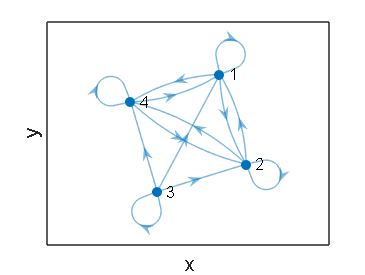

sigma_lid=1; 

fx=460;
fy=460;
cx=255;
cy=255;
image_w=640;
image_h=640;

b_g_real=[0.02,0.01,0.02];%bias 
b_a_real=[0.03,0.05,0.03];
g_real=[0;0;-9.81];


CAM_INTRISIC.FOV=pi;
CAM_INTRISIC.fx=fx;
CAM_INTRISIC.fy=fy;
CAM_INTRISIC.cx=cx;
CAM_INTRISIC.cy=cy;    
CAM_INTRISIC.image_w=image_w;
CAM_INTRISIC.image_h=image_h;
CAM_INTRISIC.tc=dtc; %相机采样频率
CAM_INTRISIC.sigma_cam=sigma_cam;
CAM_INTRISIC.sigma_tc=sigma_tc;

% All the robots share the same landmarks.
 % camera landmarks
N_LMCAMERA=4*30;% The number of camera's landmarks
%lm_camera =camera_genlandmark(N_LMCAMERA,[1,1,2],[3,3,3], scale, [2.5,2.5,1.5]); %generate camera's landmarks, 5*5=25%LiDAR_genlandmark(N_LMCAMERA,[-150, 5, -45],scale); 
lm_camera=camera_genlandmark(N_LMCAMERA,[05,10,10],[100,100,100], scale, [150,150,150]); %generate camera's landmarks, 5*5=25

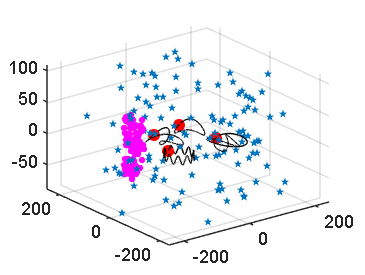

 % LiDAR landmarks
N_LMLIDAR=100;% The number of LiDAR's landmarks
lm_lidar = LiDAR_genlandmark(N_LMLIDAR,[-150, -5, -45],scale);

% Randomly assign initial positions for robots
Position0=[-80,-60,0; -40,50,0; 45,60,2; 55,-75,5];
trigK=[1,1,10;2,1,3;1,1,2; 2,3,3];
Robot=[];
for i=1:4
    [Robot(i).real_path,Robot(i).T_real0] = gen_trajectory(T_WORKING, dti, Position0(i,:),trigK(i,:));
    Robot(i).IMU_data = IMU_gendata(Robot(i).real_path,b_g_real,b_a_real,sigma_g, sigma_a, dti);
    Robot(i).camera_data =  camera_gendata(CAM_INTRISIC,lm_camera,  (T_WORKING+dtc), p_camera_in_IMU_real, R_camera_in_IMU_real,dtc, t_c_real, Position0(i,:),trigK(i,:)); 
    Robot(i).lidar_data = LiDAR_gendata(lm_lidar, sigma_lid,sigma_tl, (T_WORKING+dtl),p_lidar_in_IMU_real, R_lidar_in_IMU_real,dtl, t_l_real,Position0(i,:),trigK(i,:));
end


save("data1.mat");

